# Wave Parameter Extraction Pipeline

This MATLAB LiveScript serves as a live document to show the implementation of the SAR wave parameter extraction pipeline with additional documentation. Documentation notes are included before code blocks which explain the code which follows.

## Obtain SAR Data

[https://earth.esa.int/eogateway/documents/20142/37627/COSMO-SkyMed-Second-Generation-Mission-Products-Description.pdf](https://earth.esa.int/eogateway/documents/20142/37627/COSMO-SkyMed-Second-Generation-Mission-Products-Description.pdf)

## **Pre-Process SAR Data**

Open CosmoSkyMED image in SNAP:

- Subset image

- Save as .nc file

****TO DO:** Remove the need for this step

## 1 Import the CosmoSkyMED Data

After exporting the SAR data as a NetCDF file, use the following commands to import the data and metadata into MATLAB.

filepath = "/Users/tris/Documents/MATLAB/MSc/subset_CSKS1_DGM_B_WR_01_VV_RA_SF_20220722070221_20220722070237_small.nc";

ncInfo_SAR = ncinfo(filepath);
% Create a cosmo satellite object to store all important information.
cosmo = CosmoSkyMED(filepath,"CSK");

% Import the data.
%sarData = ncread(cosmo.Filepath,'Amplitude');
sar_latGrid = ncread(cosmo.Filepath,'lat')';
sar_lonGrid = ncread(cosmo.Filepath,'lon')';
sar_Data_import = ncread(cosmo.Filepath,'Intensity'); 
sar_Data = sar_Data_import'/mean(sar_Data_import(:)); % Normalise the intensity values to a value between 0 and 1.

Alternatively, import the data as an hdf5 file.

% filepath = "/Users/tris/Documents/MATLAB/MSc/20220722_1778608_CSG_/CSG_SSAR1_DGM_B_0301_SC1_001_VV_RA_F_20220722065043_20220722065057_1_F_57S_Z31_N00.h5";
% 
% h5Info = h5info(filepath);
% 
% % Create a structure to store imported HDF5 data
% sarData = h5read(filepath, '/IMG');
% % Display results
% figure; imshow(sarData);

### 1.1 View SAR Data

Choose whether to display a greyscale image of the imported SAR data.

% plotSARData = true;
figure;
pcolor(sar_Data);
shading("flat");
colormap("gray");
clim([0 2]);
title("COSMO-SkyMed (X-band) No Cal SAR image - 22/07/2022")
ylabel("Across Range Pixels");
xlabel("Along Range Pixels");

### 1.2 Radiometric Calibration

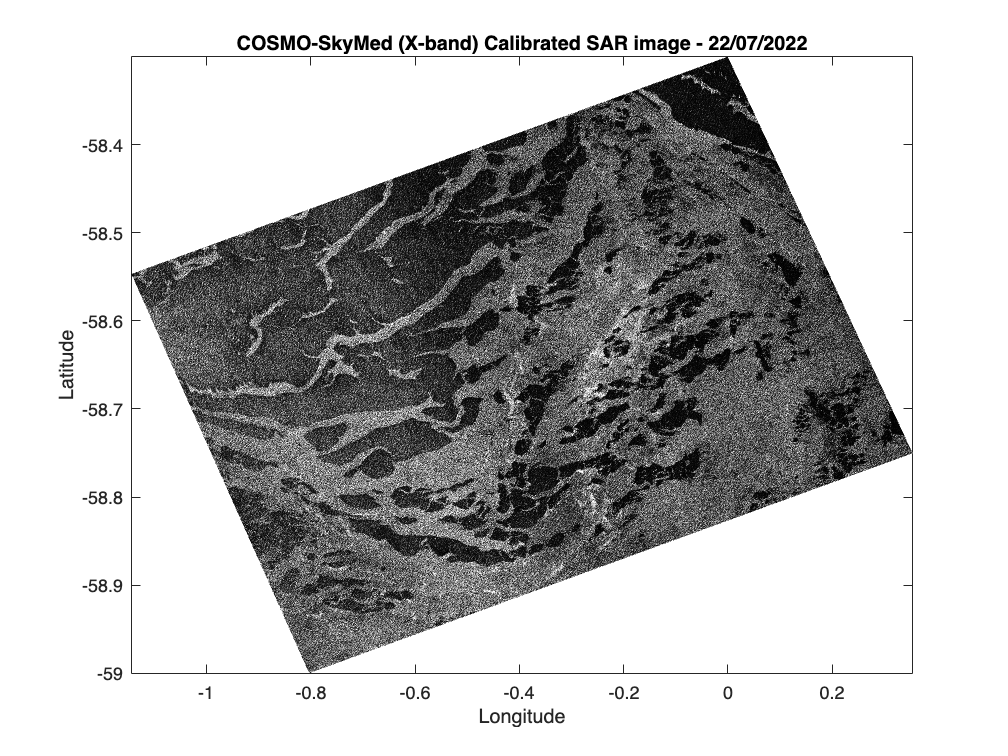

sar_Data_cal = cosmo.radiometricCalibration(sar_Data); 
sar_Data_cal = sar_Data_cal/mean(sar_Data_cal(:)); % Normalise the intensity values to a value between 0 and 1.

figure;
pcolor(sar_lonGrid,sar_latGrid,sar_Data_cal);
shading("flat");
colormap("gray");
clim([0 2]);
title("COSMO-SkyMed (X-band) Calibrated SAR image - 22/07/2022")
ylabel("Latitude");
xlabel("Longitude");

### **1.3 Take Transects**

****TO DO**: NEED TO COME UP WITH SMART WAY OF DOING open ocean DETECTION FOR THE TRANSECT selection

% Plot where the transect will be taken (use original data to view easily
% 
% figure;
% pcolor(sarData'/mean(sarData(:)));
% shading("flat");
% colormap("gray");
% clim([0 2]);
% hold on
% plot([512 512],[0 3621],'r');
% plot([0 4834],[3200-512 3200-512],'b');
% plot([0 4834],[3200 3200],'b');

Now subset the calibrated data to produce a transect.

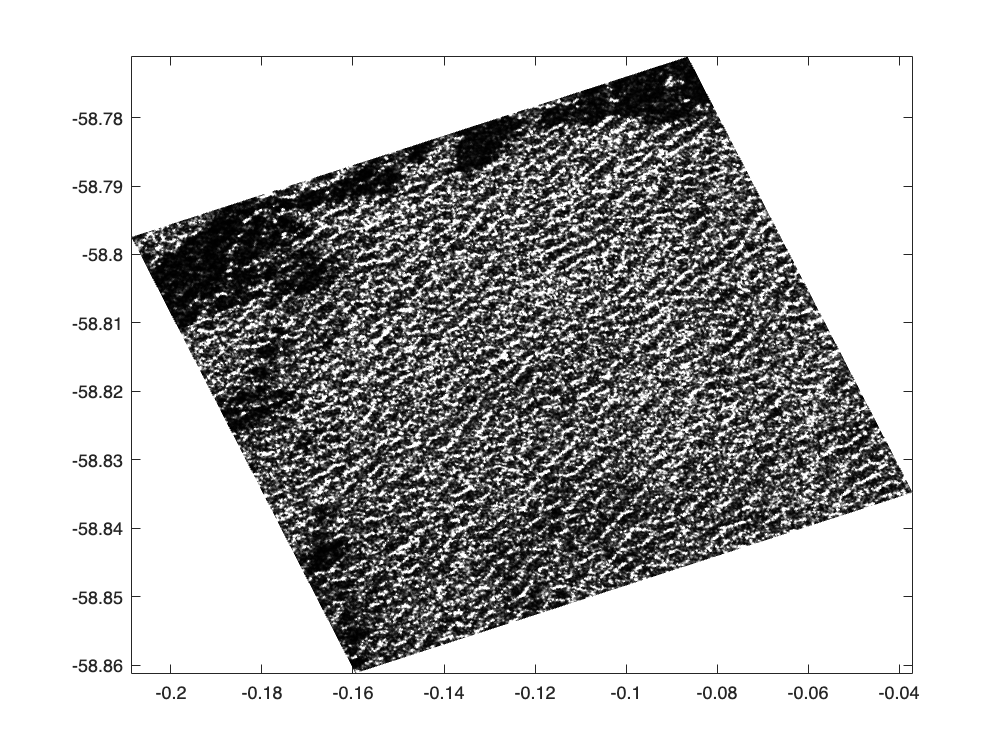

sar_transect_size = 512;
% Calculate the transect from the calibrated data
sar_transect = sar_Data_cal(1:sar_transect_size, (3200-sar_transect_size):3200-1);
sar_transect_lonGrid = sar_lonGrid(1:sar_transect_size, (3200-sar_transect_size):3200-1);
sar_transect_latGrid = sar_latGrid(1:sar_transect_size, (3200-sar_transect_size):3200-1);
% Plot the transect
figure;
pcolor(sar_transect_lonGrid,sar_transect_latGrid,sar_transect);
shading("flat");
colormap("gray");
clim([0 2]);

## 2 ERA5 Data

### 2.1 Download

Get this from the CDS_ERA5_datahandling script. ****TO DO**: Make it adjustable so that the correct date and time data can be downloaded.

### 2.2 Import from file

The data needs to be 'decoded' according to the ERA5 documentation:  https://confluence.ecmwf.int/display/CKB/ERA5%3A+data+documentation

Specifically:

"

The NetCDF wave spectra file will have the dimensions longitude, latitude, direction, frequency and time.

However, the direction and frequency bins are simply given as 1 to 24 and 1 to 30, respectively.

The **direction bins** start at 7.5 degree and increase by 15 degrees until 352.5, with 90 degree being towards the east (Oceanographic convention).

The **frequency bins** are non-linearly spaced. The first bin is 0.03453 Hz and the following bins are: f(n) = f(n-1)*1.1; n=2,30. 

The data provided is the log10 of spectra density. To obtain the spectral density one has to take to the power 10 (10 ** data). This will give the units 2D wave spectra as m**2 s radian**-1 . Very small values are discarded and set as missing values. These are essentially 0 m**2 s radian**-1.

This recoding can be done with the Python [xarray](http://xarray.pydata.org/en/stable/) package, for example:

**Units of 2D wave spectra**

Once decoded, the units of 2D wave spectra are m2 s radian-1

"

%% Get Parameters of the complete 
filepath = "/Users/tris/Documents/MATLAB/MSc/ERA5-2Dws_20220720.nc";

% Store file info in MATLAB struct
ncinfo_era5 = ncinfo(filepath);

% Get attributes
era5_lon = ncread(filepath,'longitude');
era5_lat = ncread(filepath,'latitude');
era5_time = ncread(filepath,'time');
era5_direction = ncread(filepath,'direction');
era5_frequency = ncread(filepath,'frequency');
era5_d2fd_all_5dims = ncread(filepath,'d2fd'); % 'frequency direction spectrum' Wave energy spectrum OR variance density spectrum [m^2 s / rad] : how the wave energy is distributed across different spatial and temporal scales

% Decode the direction data according to the ERA5 documentation
era5_direction_bins = ((7.5: 15: 352.5)/180*pi)'; % From ERA5 documentation

% Decode the frequency data ERA5 according to https://confluence.ecmwf.int/display/CKB/ERA5%3A+data+documentation
era5_freq_bins = zeros(1, size(era5_frequency,1));
era5_freq_bins(1) = 0.03453;
for i=2:length(era5_freq_bins)
    era5_freq_bins(i) = era5_freq_bins(i-1)*1.1;
end

% Decode the spectra according to the ERA5 documentation
era5_d2fd_all_5dims = 10.^era5_d2fd_all_5dims; % [m^2 s /rad]
era5_d2fd_all_5dims(isnan(era5_d2fd_all_5dims)) = 0; % Necessary step according to the ERA5 documentation

### **2.3 Define Points of Interest**

These are the points in the single level data (from step 2) that we are interested in view the spectrum of (in step 4).

latitude_of_interest = -55;
longitude_of_interest = -5;
time_of_interest_index = 9;
time_of_interest = era5_time(time_of_interest_index); % this should be the same as the time index chosen in step 2 for all plots.

### **2.4 Get the Wave spectrum at Points of Interest (Step 2.3)**

% Find the slice that matches what we are plotting in the single level data
% in step 2.
time_position_match = find(era5_time == time_of_interest);
lat_position_match = find(era5_lat == latitude_of_interest);
lon_position_match = find(era5_lon == longitude_of_interest);


era5_d2fd(:,:) = era5_d2fd_all_5dims(lon_position_match,lat_position_match,:,:,time_position_match);

### **2.5 Plot the 2D wave spectra**

Note when working with the data: the dimensions are usually in the order lon lat time OR lon lat dir frq time. This can be checked by using ncinfo to get a structure of the file and then looking at the "Dimensions" field.

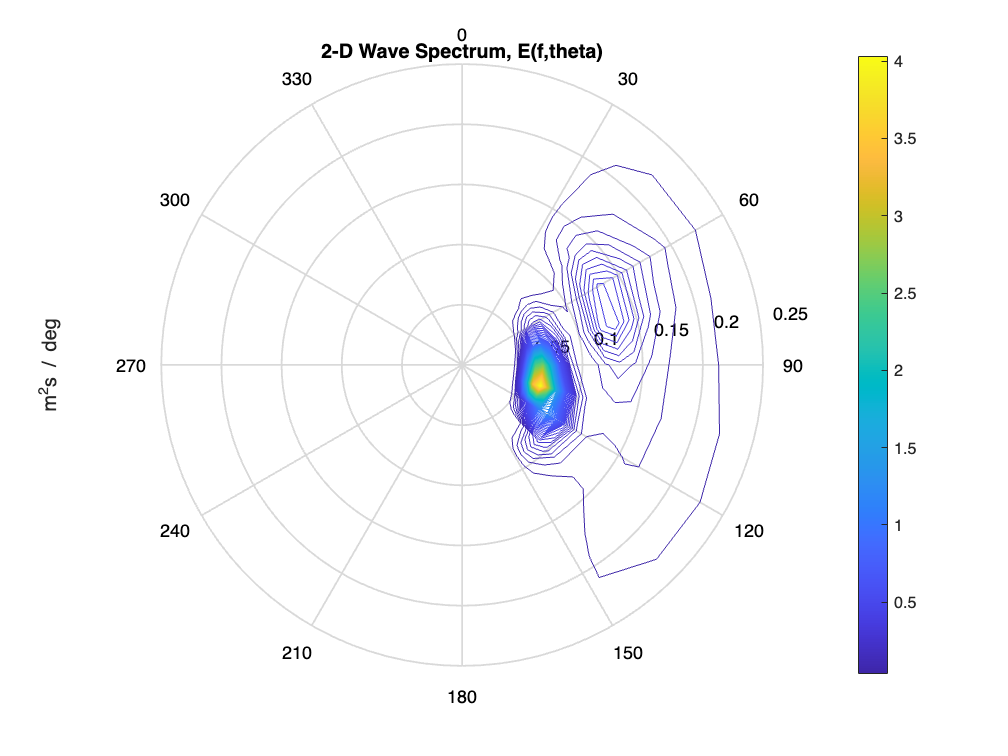

plotERA52Dspectrum = true;
if plotERA52Dspectrum 
    % Plot the 2D spectra
    figure;
    PolarContour(era5_d2fd, era5_freq_bins, 0.25);
    title("2-D Wave Spectrum, E(f,theta)")
end 

### 2.6 Calculate the parameters for the data located at specified latitude, longitude ans specified time

These equations are taken from ?

% % Calculate the wave spectrum for all time
% era5_d2fd_all_time = zeros(size(era5_d2fd_all,5),size(era5_d2fd_all,3),size(era5_d2fd_all,4)); % dimensions t direc freq
% for t = 1:size(era5_d2fd_all,5)
%     era5_d2fd_match(:,:) = era5_d2fd_all(lon_position_match,lat_position_match,:,:,t); % Dimensions are: direction,frequency
%     era5_d2fd_all_time(t,:,:) = 10.^era5_d2fd_match;
%     era5_d2fd_all_time(isnan(era5_d2fd_all_time))=0; % Otherwise all values are just N
% end

#### Significant Wave Height

% Calculate the 0th order moments (m_n) [Eq.8]
era5_m0_derived = trapz(era5_direction_bins,trapz(era5_freq_bins,1*era5_d2fd,2),1); %[Eq.8], dimension 2,3 = direc,freq
% era5_m0_derived_all_time = trapz(era5_direction_bins,trapz(era5_freq_bins,1*era5_d2fd_all_time,3),2); %[Eq.8], dimension 2,3 = direc,freq

% Calculate the significant wave height (Hs) [Eq.4]
era5_Hs_derived = 4*sqrt(era5_m0_derived); 
% era5_Hs_derived_all_time = 4*sqrt(era5_m0_derived_all_time); 

#### Mean Wave period

% Calculate the -1st order moments (m_n)
era5_m_neg1_derived = trapz(era5_direction_bins,trapz(era5_freq_bins,(1./era5_freq_bins).*era5_d2fd,2),1); %[Eq.8]
% era5_m_neg1_derived_all_time = zeros(size(era5_d2fd_all,5),1);
% for t = 1:size(era5_d2fd_all,5)
%     spectrum(:,:) = era5_d2fd_all_time(t,:,:);
%     era5_m_neg1_derived_all_time(t,1) = trapz(era5_direction_bins,trapz(era5_freq_bins,(1/era5_freq_bins).*era5_spectrum_all_time,2),1); %[Eq.8]
% end

% Calculate the mean wave period (Tm) [Eq.5]
era5_Tm_derived = era5_m_neg1_derived/era5_m0_derived; % [Eq.5]
% era5_Tm_derived_all_time = era5_m_neg1_derived_all_time./era5_m0_derived_all_time; % [Eq.5]

#### Mean Wave direction

% Calculate the angular moments [Eq.9&10]
era5_a1 = trapz(era5_freq_bins,trapz(era5_direction_bins,cos(era5_direction_bins).*era5_d2fd,1),2); %[Eq.9]
era5_b1 = trapz(era5_freq_bins,trapz(era5_direction_bins,sin(era5_direction_bins).*era5_d2fd,1),2); %[Eq.10]
% for t = 1:size(era5_d2fd_all,5)
%     spectrum(:,:) = era5_d2fd_all_time(t,:,:); % dimenstions: direc, freq
%     era5_a1_all_time(t) = trapz(era5_freq_bins,trapz(era5_direction_bins,cos(era5_direction_bins)'.*era5_spectrum_all_time,1),2); %[Eq.9]
%     era5_b1_all_time(t) = trapz(era5_freq_bins,trapz(era5_direction_bins,sin(era5_direction_bins)'.*era5_spectrum_all_time,1),2); %[Eq.10]
% end

% Calculate the mean Direction of the wave
era5_direction_derived = atand(era5_b1./era5_a1); %[Eq.6]
era5_direction_derived_radians = era5_direction_derived * pi/180;
% era5_direction_derived_all_time = atand(era5_b1_all_time./era5_a1_all_time); %[Eq.6]

#### **Spectral Denisty**

% Total variance/energy of the waves = spectral density integrated over all
% frequencies and wave numbers at specified time of interest
% total_variance_or_energy = trapz(trapz(era5_d2fd,2),1);

### 2.7 Plot Wave Direction

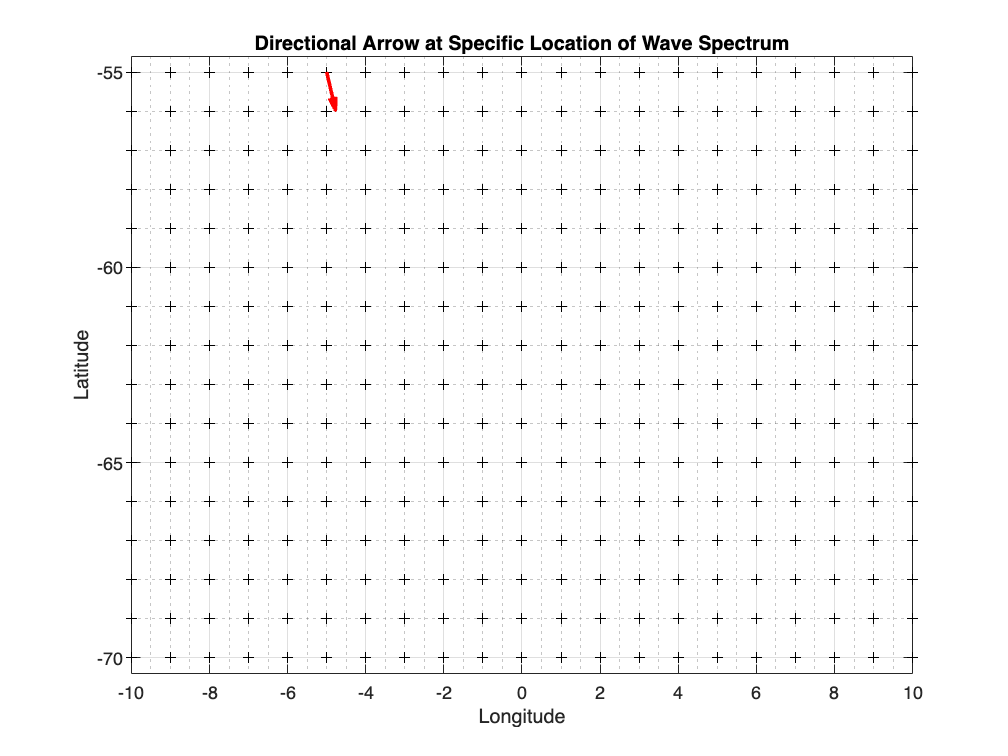

% Plot the Lat-Long x-y grid 
[era5_lonGrid, era5_latGrid] = meshgrid(era5_lon,era5_lat);

% Plot the grid (optional, for context)
figure;
plot(era5_lonGrid, era5_latGrid, "k+");  % Plot grid points for reference
hold on;
% Plot the directional arrow at the specific latitude and longitude
quiver(longitude_of_interest, latitude_of_interest, cos(era5_direction_derived_radians), sin(era5_direction_derived_radians), ...
       'AutoScale', 'off', 'MaxHeadSize', 2, 'LineWidth', 2, 'Color', 'r');

% Adjust plot settings
title('Directional Arrow at Specific Location of Wave Spectrum');
xlabel('Longitude'); ylabel('Latitude');
axis equal;  % Ensure equal scaling of axes
grid on;
grid minor;
hold off;

# Open Ocean H&H

## 1 First guess wave number spectrum

*This is derived from the Directional Wave Buoy (ERA5) Wave Spectrum data.*

- **Note: The wave number spectrum is the projection of the wave spectrum (f,theta) into the wavenumber (kx,ky) domain.** **"**Where the wave spectrum considers the sea as a function of space and time, η(x, y, t), the ocean can also be considered as a function of space at a single moment in time. This idea is useful for remote sensing applications."  "The wave-number spectrum, E(kx,ky) is useful for remote sensing applications, and the frequency-direction spectrum, E(f,θ), is used for wave models"  (Ryan 4022). pg 20-21

- This needs to be a plot of the ERA5 d2fd data on a kx ky grid. See the comments below but need to look at how it is done in Holthuijsen.

- Make the plot and then compare to the HH paper. Plot next to the f theta plot to see the difference and the translation.

gravity = 9.81;

era5_omega = 2 * pi * era5_freq_bins;
era5_k = (2*pi*era5_freq_bins).^2 ./ gravity; % from deep water approximation of omega = sqrt(gk), [Eq.5.4.18 Holthuijsen]
era5_kx = era5_k .* cos(era5_direction_derived_radians); % [rad/m] [Eq.3.5.19b Holthuijsen]
era5_ky = era5_k .* sin(era5_direction_derived_radians); % [rad/m] [Eq.3.5.19b Holthuijsen]

% According to Holthuijsen and Ryan 4022 pg 20 onwards:
% Wave phase speed (c_w) for deep water [Eq.3.22 Ryan 4022]
% era5_cw_wave_speed = gravity ./ (era5_omega); % c_0, [Eq.5.4.24 Holthuijsen]
era5_cw_wave_speed = era5_omega ./era5_k; % c, [Eq.3.5.36 Holthuijsen] same as above

% Group wave speed (c_g)
era5_n_dispersion_scaling_factor = 0.5; % 0.5 is used for deep water, [Eq.5.4.32 Holthuijsen]
era5_cg_group_wave_speed = era5_n_dispersion_scaling_factor * era5_cw_wave_speed; % [Eq.5.4.32 Holthuijsen]

% Calculate the wave number spectrum E(kx,ky) [Eq.3.17 Ryan 4022]
era5_E_kx_ky = (era5_cw_wave_speed .* era5_cg_group_wave_speed) ./ era5_omega .* era5_d2fd; % [Eq.3.5.36 Holthuijsen]
first_guess_wave_spectrum = era5_E_kx_ky;

% Zero-pad the ERA5 matrix so that it is square
era5_E_kx_ky_zero_padded = zeros(30,30);
era5_E_kx_ky_zero_padded(1:24,1:30) = first_guess_wave_spectrum;
first_guess_wave_spectrum_zero_padded = era5_E_kx_ky_zero_padded;

%% Plot the wave number spectrum E(kx,ky) and wave spectrum E(f,theta)
%% With Zero padding to make the data square.
figure('Position', [100, 100, 1200, 400]);
subplot(1,2,1);
contour(era5_kx, era5_ky, first_guess_wave_spectrum_zero_padded);
xlim([-0.01 0.01]);
ylim([-0.05 0.05]);
xlabel('k_x [rad/m]'); ylabel('k_y [rad/m]');
title("Extrapolated 2-D wave number spectrum E(k_x,k_y) [m^2 s/rad]");
subplot(1,2,2);
PolarContour(era5_d2fd, era5_freq_bins, 0.25);
title("2-D Wave Spectrum, E(f,theta)");

## 2 First Guess SAR Spectrum - H&H's Sar Imaging of Ocean Waves *pg.2*

*This is derived from the First Guess Wave Number Spectrum.*

- Figure our where in the paper this is and then compute the SAR spectrum from the ERA 5 first guess wave spectrum in step 1

- Plot these on kx ky grid - might need to limit the Fmax value as shown in Fig 3 of HH91

In H&H this is defined as the SAR image amplitude spectrum I^S_k (pg.5)

### SAR Image parameters

% Import the functions
handh = hAndH1991Functions;

Read in SAR metadata values.

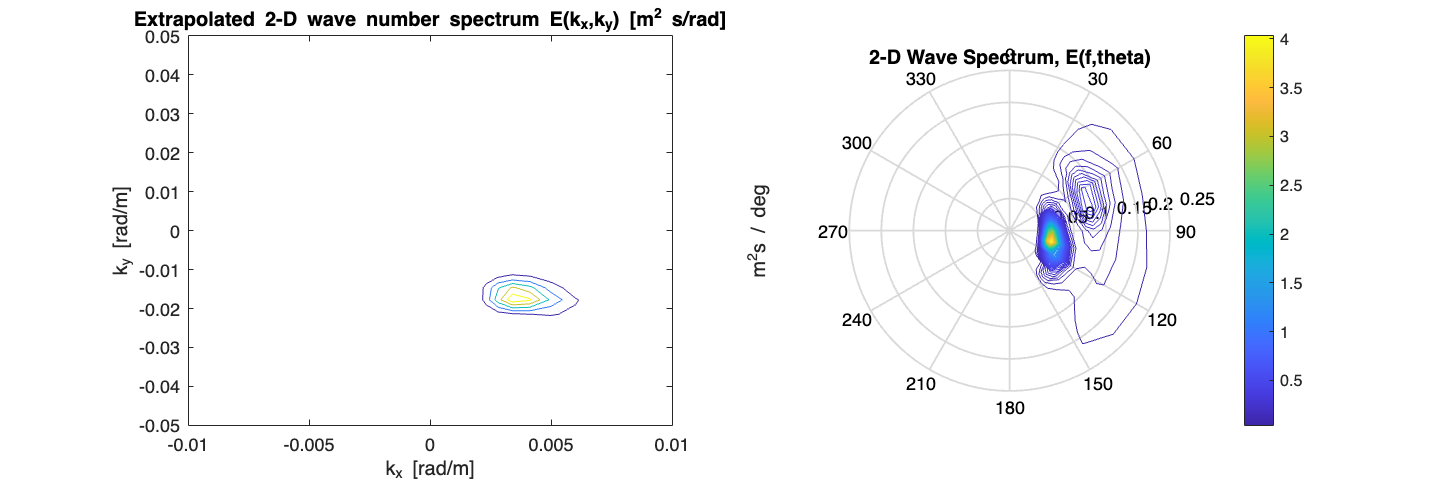

%% Import the SAR metadata attributes
metadata_attributes = ncinfo(cosmo.Filepath,'Metadata_Group').Groups(1).Attributes;


[~,matching_row_number] = ismember("mds1_tx_rx_polar", {metadata_attributes.Name});
sar_polarisation = metadata_attributes(matching_row_number(1)).Value;

incident_angle = ncread(cosmo.Filepath,"incident_angle");
sar_center_incidence_angle_degrees = incident_angle(sar_transect_size/2, sar_transect_size/2); % center of the transect

% Get the k_l variable using the direction of the SAR look.
[~,matching_row_number] = ismember("antenna_pointing", {metadata_attributes.Name});
sar_look_metadata = metadata_attributes(matching_row_number(1)).Value;

[~,matching_row_number] = ismember("range_spacing", {metadata_attributes.Name});
sar_dy = metadata_attributes(matching_row_number(1)).Value;
[~,matching_row_number] = ismember("azimuth_spacing", {metadata_attributes.Name});
sar_dx =metadata_attributes(matching_row_number(1)).Value;

% Get the slant range
[~,matching_row_number] = ismember("slant_range_to_first_pixel", {metadata_attributes.Name});
sar_slant_range = metadata_attributes(matching_row_number(1)).Value;

### Frozen Surface Contribution *pg.3-4 *

*First there are a few missing variables that need to be instantiated.*

% [pg43, Hasselmann, 1990] - "...in all cases as mu = 0.5 1/sec and gamma = 0.
% This is consistent with field and laboratory measurements (cf. Keller and Wright, 1975)"
mu = 0.5;

[sar_look,era5_kl] = handh.klUsingSARlook(sar_look_metadata,era5_ky);

*This is the RAR component and RAR imaging mechanism.*

% Tilt MTF - the change in incidence angle is due to the change in the slope of the wave face
Tt_k = handh.tiltMTF(sar_polarisation, sar_center_incidence_angle_degrees, era5_kl); % [Eq.5, H&H 1991] 

% Hydrodynamic MTF - the interactions between short and long waves, which modulate the energy and wave number of the short, Bragg scattering, ripple waves
Th_k = handh.hydrodynamicMTF(era5_omega, mu, era5_k, era5_ky); % [Eq.6, H&H 1991] 

% RAR MTF calculation
TR_k = handh.rarMTF(Tt_k,Th_k); % [Eq.4, H&H 1991] 

### Motion Effects *pg.4-5*

*Compensation for velocity bunching caused by the orbital velocity of the long waves, which produces a Doppler shift in the received, return signal. *

***** TO DO: look at calculating the satellite velocity from the metadata rather than hardcoding? (see Ryan's 4022 comments on the Sentinel data - pg.48)***

% Range Velocity MTF 
Tv_k = handh.rangeVelocityMTF(era5_omega, sar_center_incidence_angle_degrees, era5_kl, era5_k); % [Eq.17, H&H 1991] 

% Velocity Bunching MTF 
sar_platform_velocity = 7541.89; %m/s from Giacomo's output file.
sar_beta = handh.beta(sar_slant_range, sar_platform_velocity); %[Eq.15, H&H 1991]
Tvb_k = handh.velocityBunchingMTF(sar_beta, era5_kx, Tv_k); % [Eq.24, H&H 1991] 

% Net SAR imaging MTF
TS_k = handh.sarImagingMTF(TR_k, Tvb_k); %[Eq.27, H&H 1991]

### General nonlinear mapping relation *pg.5-6*

*The reasoning for doing this is given in H&H on pg 5 in the paragraph before section 3.*

"To determine the dependence of the SAR image Fourier components IS_k on the wave Fourier components in the general nonlinear case, we first apply a Fourier transform to the basic mapping relation [Eq.20, H&H 1991]... this yields the SAR image variance soectrum PS_k [Eq.30, H&H 1991]"

% Giacomo's code assumes that dx and dy are always the same but this is not
% always the case for all satellites.
% sar_dk = (2*pi)/(sar_dx * sar_transect_size);
% sar_kx = -pi / sar_dx + (1:sar_transect_size) * sar_dk;
% sar_ky = sar_kx';

sar_dkx = (2*pi)/(sar_dx * sar_transect_size);
sar_kx = -pi / sar_dx + (1:sar_transect_size) * sar_dkx;
sar_dky = (2*pi)/(sar_dx * sar_transect_size);
sar_ky = (-pi / sar_dx + (1:sar_transect_size) * sar_dky)';

#### 1. Orbital Velocity Covariance Function

% Orbital velocity covariance function
% Note Ryan does this calculation differently, he uses cumtrapz and
% calculates the difference between each value in the era5_k vector. My
% understanding of the formula is different, I see it as a 2D IFFT so does this person: https://github.com/eltjonqef/OceanSARImagingSimulator/blob/main/SAR_imaging.py
fv_r = handh.orbitalVelocityCovarianceFunction(first_guess_wave_spectrum_zero_padded,Tv_k);  %[Eq.43, H&H 1991]

figure('Position', [100, 100, 1200, 400]);
subplot(1,2,1);
contour(era5_kx, era5_ky, abs(fv_r));
xlabel('k_x [rad/m]'); ylabel('k_y [rad/m]');
title("Orbital Velocity Covariance Function, f^v(r)");
subplot(1,2,2);
contour(abs(fv_r));

#### 2. Calculate Inverses

***These are the inverse calculations - NOT SURE IF CALCULATION IS CORRECT***

% % Note: Git resource does a rot90 function instead of this... not sure
% % which is correct.
first_guess_wave_spectrum_zero_padded_inv = flipud(fliplr(first_guess_wave_spectrum_zero_padded));
TR_k_inv = flipud(fliplr((TR_k)));
Tv_k_inv = flipud(fliplr((Tv_k)));

% figure;
% contour(era5_kx, era5_ky, first_guess_wave_spectrum_zero_padded_rotated_90);
% xlabel('k_x [rad/m]'); ylabel('k_y [rad/m]');
% % xlim([-0.01 0.01]);
% % ylim([-0.05 0.05]);
% xlabel('k_x [rad/m]'); ylabel('k_y [rad/m]');
% title("Extrapolated 2-D wave number spectrum E(k_x,k_y) [m^2 s/rad]");

#### 3. Autocovariance function of the image intensity

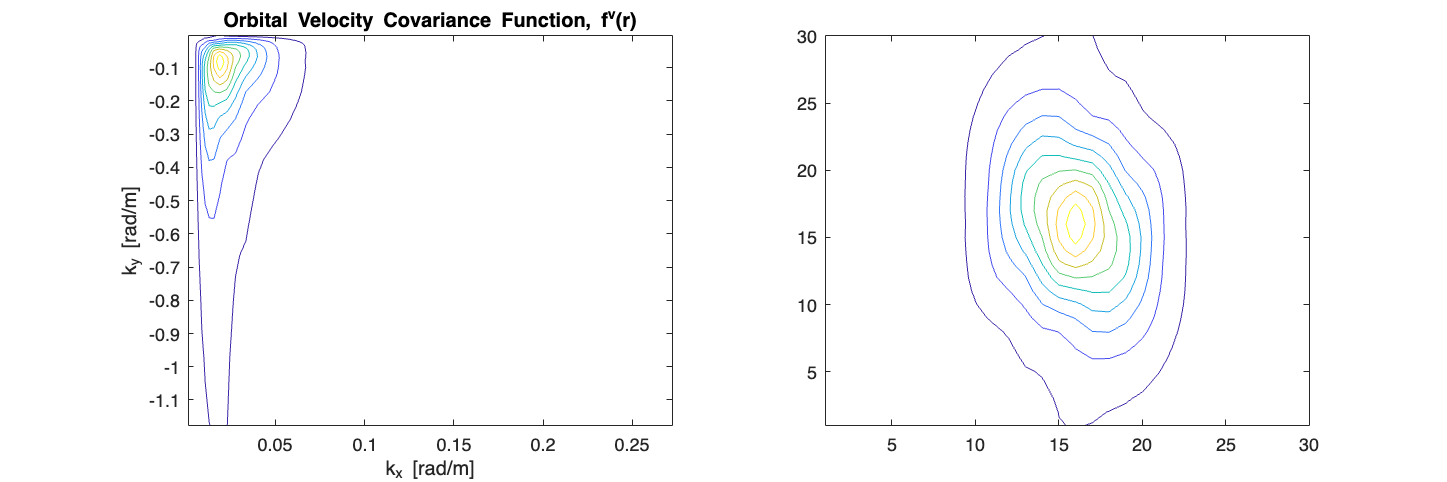

% Autocovariance function of the image intensity, I_R(x)
fR_r = handh.rarImageIntensityAutocovariance(first_guess_wave_spectrum_zero_padded,TR_k,first_guess_wave_spectrum_zero_padded_inv,TR_k_inv);  %[Eq.47, H&H 1991]

figure('Position', [100, 100, 1200, 400]);
subplot(1,2,1);
contour(era5_kx, era5_ky, abs((fR_r)));
xlabel('k_x [rad/m]'); ylabel('k_y [rad/m]');

title("RAR Image Intensity Autocovariance function, f^R(r)");
subplot(1,2,2);
contour(abs((fR_r)));

#### 4. Covariance function of the image intensity and the orbital velocity

% Covariance of RAR Image Intensity, I_R(x), and the orbital velocity, v(x)
fRv_r = handh.rarImageIntensityCovariance(first_guess_wave_spectrum_zero_padded, TR_k, Tv_k, first_guess_wave_spectrum_zero_padded_inv, TR_k_inv, Tv_k_inv);  %[Eq.48, H&H 1991]

figure('Position', [100, 100, 1200, 400]);
subplot(1,2,1);
contour(era5_kx, era5_ky, abs((fRv_r)));
xlabel('k_x [rad/m]'); ylabel('k_y [rad/m]');
title("RAR Image Intensity and Orbiral Velocity Covariance function, f^Rv(r)");
subplot(1,2,2);
contour(abs((fRv_r)));

#### 2. Calculate Inverses

***These are the inverse calculations - NOT SURE IF CALCULATION IS CORRECT***

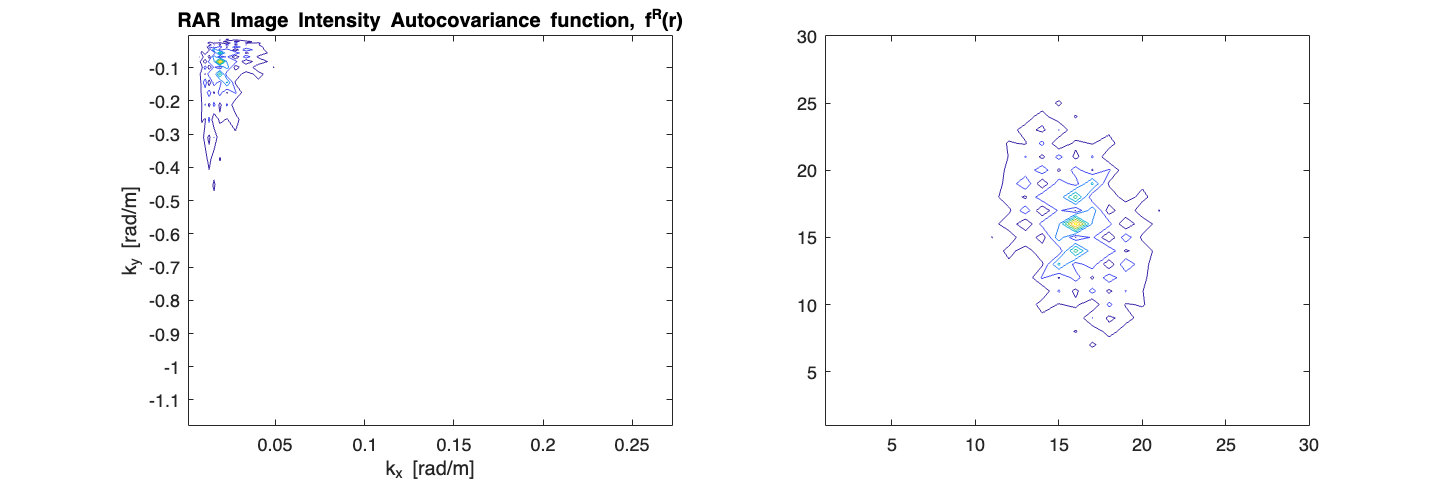

% % Note: Git resource does a rot90 function instead of this... not sure
% % which is correct.
fRv_r_inv = flipud(fliplr((fRv_r)));
TS_k_inv = flipud(fliplr(TS_k));
% figure;
% contour(era5_kx, era5_ky, first_guess_wave_spectrum_zero_padded_rotated_90);
% xlabel('k_x [rad/m]'); ylabel('k_y [rad/m]');
% % xlim([-0.01 0.01]);
% % ylim([-0.05 0.05]);
% xlabel('k_x [rad/m]'); ylabel('k_y [rad/m]');
% title("Extrapolated 2-D wave number spectrum E(k_x,k_y) [m^2 s/rad]");

#### 5. Spectral Expansion

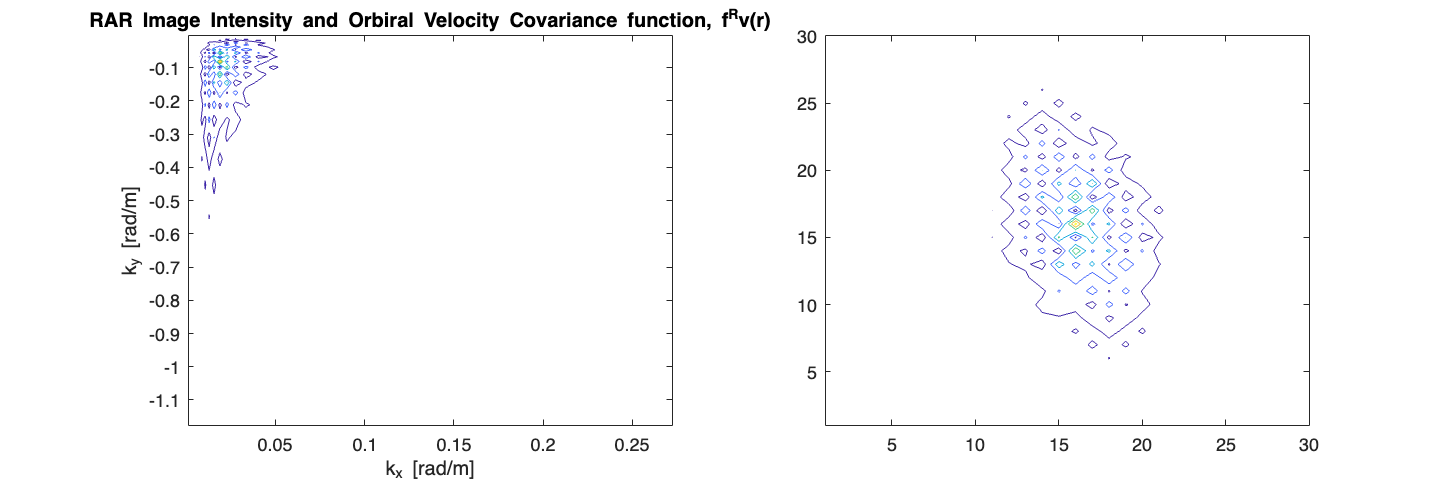

nonlinearity_order_n = 1;

% Spectral Expansion Terms
PS_2n = handh.spectralExpansion2nTerm(nonlinearity_order_n,fv_r); %[Eq.51, H&H 1991]
PS_2n_minus_1 = handh.spectralExpansion2nMinus1Term(nonlinearity_order_n , fv_r, fRv_r, fRv_r_inv);  %[Eq.52, H&H 1991]

fRv_0 = fRv_r(1,1);
PS_2n_minus_2 = handh.spectralExpansion2nMinus2Term(nonlinearity_order_n, fv_r, fRv_r, fRv_r_inv, fRv_0, fR_r); %[Eq.53, H&H 1991] NB CHECK THIS FORMULA WHAT IS fr_r??


**Quasilinear approximation**

% Mean square azimuthal displacement 
xi_sqr = handh.meanSquareAzimuthalDisplacement(sar_beta, fv_r); %[Eq.44, H&H 1991]

% Quasilinear coefficient: Nonlinear azimuthal cutoff factor
ql_coefficient = exp(-era5_kx.^2 .* xi_sqr); %[Eq.56, H&H 1991]


% Calculate the SAR Image Variance Spectrum P^S(k) Eq.50

for m = (2*nonlinearity_order_n -2) : 2*nonlinearity_order_n
   if m == 2*nonlinearity_order_n -2
       PS_k = (era5_kx .* sar_beta).^m .* PS_2n_minus_2;
   
   elseif m == 2*nonlinearity_order_n - 1
       PS_k = PS_k + (era5_kx .* sar_beta).^m .* PS_2n_minus_1;

   elseif m == 2*nonlinearity_order_n
       PS_k = PS_k + (era5_kx .* sar_beta).^m .* PS_2n;

   end 
end

PS_k = PS_k .* ql_coefficient;

figure;
contour(era5_kx./mean(era5_k), era5_ky./mean(era5_k), abs(PS_k));
xlabel('k_x [rad/m]'); ylabel('k_y [rad/m]');
% xlim([-0.01 0.01]);
% ylim([-0.3 0.1]);
xlabel('k_x [rad/m]'); ylabel('k_y [rad/m]');
title("SAR Image Variance Spectrum P^S(k)");


#### 6. Other formulas and things discussed in the paper:

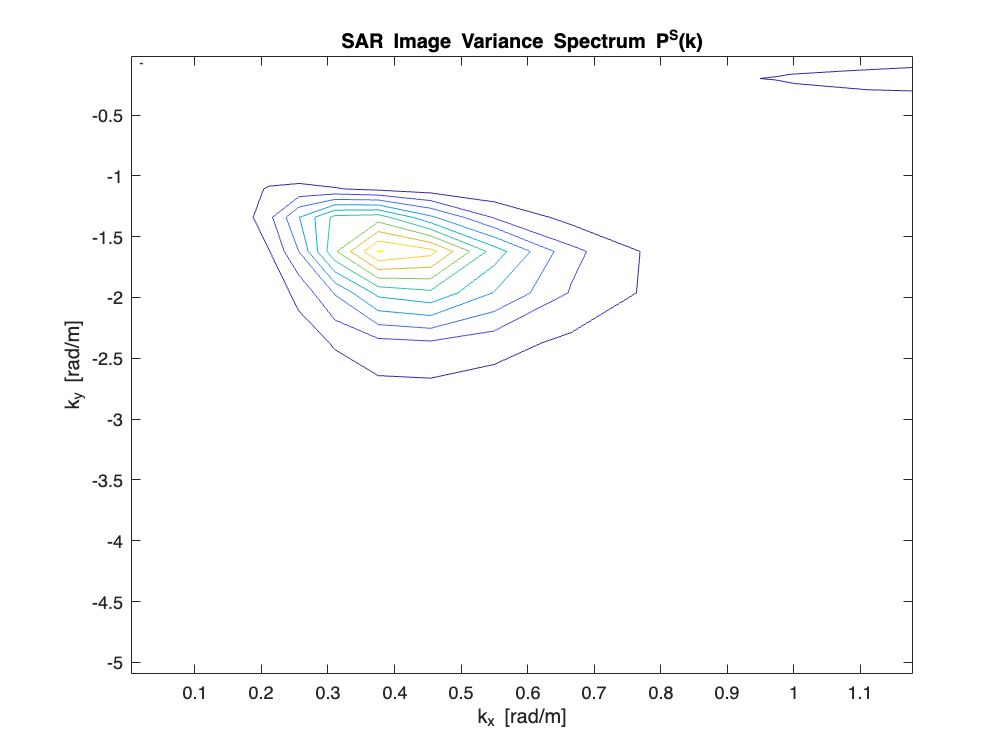

% PS_1(k) linear term of the Image variance spectrum (linear mapping
% transform)
PS_1_k = handh.linearMappingTransform(TS_k, first_guess_wave_spectrum_zero_padded, TS_k_inv, first_guess_wave_spectrum_zero_padded_inv); %[Eq.26 & Eq.55, H&H 1991]


% Quasilinear Approximation / Quasilinear mapping transform
PS_ql = ql_coefficient .* PS_1_k; %[Eq.56, H&H 1991]

figure('Position', [100, 100, 1200, 400]);
subplot(1,2,1);
contour(era5_kx, era5_ky, PS_ql);
xlabel('k_x [rad/m]'); ylabel('k_y [rad/m]');
title("Quasilinear Approximation of the SAR Image Variance Spectrum, P^S_q_l (k)");
subplot(1,2,2);
contour(PS_ql);
% Calculate the SAR Image Variance Spectrum P^S(k) Eq.58
PR_ql = ql_coefficient .* PS_2n_minus_2; % Pure RAR spectrum
Pint_ql = ql_coefficient .* (era5_kx .* sar_beta) .* PS_2n_minus_1; % Quasilinear interference term
Pvb_ql = ql_coefficient .* (era5_kx .* sar_beta).^2 .* PS_2n; % Pure quasilinear velocity bunching spectrum
for m = (2*nonlinearity_order_n -2) : 2*nonlinearity_order_n
   if m == 2*nonlinearity_order_n -2


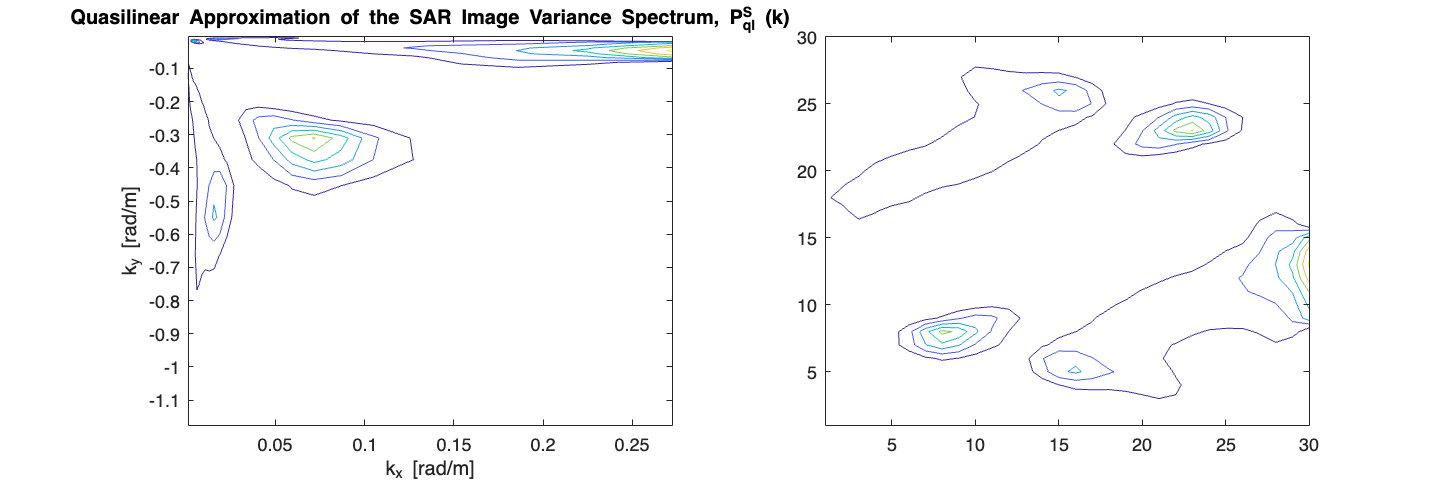


   elseif m == 2*nonlinearity_order_n - 1

   elseif m == 2*nonlinearity_order_n
       PS_k = PS_k + (era5_kx .* sar_beta).^m .* PS_2n;

   end 
end

PS_ql = PR_ql + Pint_ql + Pvb_ql; % [Eq.57, H&H 1991]


% Filter functions [Eq.60, H&H 1991]
filter_coefficient = exp(-era5_kx .* xi_sqr);
HR_k = filter_coefficient .* abs(TR_k).^2;
Hint_k = filter_coefficient .* (TR_k .* conj(Tvb_k) + conj(TR_k) .* Tvb_k);
Hvb_k = filter_coefficient .* abs(Tvb_k).^2;
HS_k = filter_coefficient .* abs(TS_k).^2;


figure;






### PREVIOUS ATTEMPT

Here I was using variables form the SAR data like sar_k and sar_ky instead of using the era5 data - I THINK THIS IS WRONG.

#### Frozen Surface Contribution *pg.3-4 *

*First there are a few missing variables that need to be instantiated.*

% [pg43, Hasselmann, 1990] - "...in all cases as mu = 0.5 1/sec and gamma = 0.
% This is consistent with field and laboratory measurements (cf. Keller and Wright, 1975)"
mu = 0.5;

% From Giacomo's code:
sar_dkx = (2*pi)/(sar_dx*sar_transect_size);
sar_kx = -pi / sar_dx + (1:sar_transect_size) * sar_dkx;
sar_ky = sar_kx';

% Formulae are from [Holtjuisen]
sar_k = sqrt(sar_kx.^2 + sar_ky.^2);
sar_omega = sqrt(sar_k*gravity); % [Eq.5.4.24 Holthuijsen]
% minimum_wavelength = 2*pi./max(sar_k); %[m]

[sar_look,sar_kl] = handh.klUsingSARlook(sar_look_metadata,sar_ky);

*This is the RAR component and RAR imaging mechanism.*

% Tilt MTF - the change in incidence angle is due to the change in the slope of the wave face
Tt_k = handh.tiltMTF(sar_polarisation, sar_center_incidence_angle_degrees, sar_kl); % [Eq.5, H&H 1991] 

% Hydrodynamic MTF - the interactions between short and long waves, which modulate the energy and wave number of the short, Bragg scattering, ripple waves
Th_k = handh.hydrodynamicMTF(sar_omega, mu, sar_k, sar_ky); % [Eq.6, H&H 1991] 

% RAR MTF calculation
TR_k = handh.rarMTF(Tt_k,Th_k); % [Eq.4, H&H 1991] 

#### Motion Effects *pg.4-5*

*Compensation for velocity bunching caused by the orbital velocity of the long waves, which produces a Doppler shift in the received, return signal. *

***** TO DO: look at calculating the satellite velocity from the metadata rather than hardcoding? (see Ryan's 4022 comments on the Sentinel data - pg.48)***

% Range Velocity MTF 
Tv_k = handh.rangeVelocityMTF(sar_omega, sar_center_incidence_angle_degrees, sar_kl, sar_k); % [Eq.17, H&H 1991] 

% Velocity Bunching MTF 
sar_platform_velocity = 7541.89; %m/s from Giacomo's output file.
sar_beta = handh.beta(sar_slant_range, sar_platform_velocity); %[Eq.15, H&H 1991]
Tvb_k = handh.velocityBunchingMTF(sar_beta, sar_kx, Tv_k); % [Eq.24, H&H 1991] 

% Net SAR imaging MTF
TS_k = handh.sarImagingMTF(TR_k, Tvb_k); %[Eq.27, H&H 1991]

CODE FROM FRANCESCA


x = (0:511)*sar_dx;
y = x';
r = sqrt(x.^2+y.^2);

nonLinOrder = 1;
n = nonLinOrder;
% Calc beta

% Tv_k_comp = handh.rangeVelocityTF(omega, sar_center_incidence_angle_degrees, -kl, -k);
Tv_k_comp = fliplr(Tv_k);
Tv_k_comp(isnan(Tv_k_comp)) = 0;

% figure;
% contour(real(Tv_k));
% shading("flat");
% figure;
% contour(real(Tv_k_comp));
% shading("flat");

% Orbital velocity
fv_r = trapz(sar_kx,trapz(sar_ky, era5_spectrum_kxky.*abs(Tv_k).^2.*exp(1i.*sar_k.*r),2),1);

% rarImageIntensityAutocovariance [Eq.47]
TR_k(isnan(TR_k)) = 0;
era5_spectrum_kxky_comp = flipud(fliplr(era5_spectrum_kxky));
TR_k_comp = fliplr(TR_k); % same as the code below:
% Tt_k_neg = handh.tiltMTF(sar_polarisation, sar_center_incidence_angle_degrees, -1*kl);
% Th_k_neg = handh.hydrodynamicMTF(omega, mu, -1*k, -1*ky);
% TR_k_inv_test = handh.rarMTF(Tt_k,Th_k);
era5_spectrum_kxky(isnan(era5_spectrum_kxky)) = 0;
TR_k(isnan(TR_k)) = 0;
era5_spectrum_kxky_comp(isnan(era5_spectrum_kxky_comp)) = 0;
TR_k_comp(isnan(TR_k_comp)) = 0;
sar_k(isnan(sar_k)) = 0;
r(isnan(r)) = 0;
fR_r = 0.5 * trapz(sar_kx, trapz(sar_ky,((era5_spectrum_kxky.*abs(TR_k).^2)+(era5_spectrum_kxky_comp.*abs(TR_k_comp).^2)).*exp(1i.*sar_k.*r),2),1);

%rarImageIntensityCovariance [Eq.48]
%Tv_k_comp = fliplr(Tv_k);
Tv_k_comp = handh.rangeVelocityTF(omega, sar_center_incidence_angle_degrees, -sar_kl, -sar_k);

ryan_c = physconst('LightSpeed');
Tv_k_comp(isnan(Tv_k_comp))=0;
fRv_r = 0.5 * trapz(sar_kx,trapz(sar_ky,((ryan_c.*TR_k.*conj(Tv_k))+(era5_spectrum_kxky_comp.*conj(TR_k_comp)).*Tv_k_comp).*exp(1i.*sar_k.*r),2),1);

% Velocity Bunching MTF
Tvb_k = (-1i*beta*sar_kx)*Tv_k; %[Eq.24]

% SAR Imaging MTF
TS_k = TR_k + Tvb_k; %[Eq.27]

% Azimuthal cutoff factor (mean square azimuthal displacement)
xi_squared = beta^2 * trapz(sar_kx,trapz(sar_ky,abs(Tv_k).^2 .* era5_spectrum_kxky ,2),1); % [Eq.44]

% Spectral expansion PS_1
% Tvb_k_comp = (-1i*beta*-kx)*Tv_k_comp;
Tvb_k_comp = fliplr(Tvb_k);
Tvb_k_comp(isnan(Tvb_k_comp)) = 0; % Handle NaN values (optional)
TS_k_comp = TR_k_comp+Tvb_k_comp;
TS_k_comp(isnan(TS_k_comp)) = 0; % Handle NaN values (optional)
PS_k_1 = (abs(TS_k).^2 .* era5_spectrum_kxky./2) + (abs(TS_k_comp).^2 .* era5_spectrum_kxky_comp./2); %[Eq.26]
PS_k_1(isnan(PS_k_1)) = 0; % Handle NaN values (optional)


**Calculate the generated SAR spectrum**

% Quasilinear approximation 
PS_ql_k = exp(-(sar_kx.^2).*xi_squared).*PS_k_1;% [Eq.56]
PS_ql_k(isnan(PS_ql_k)) = 0; % Handle NaN values (optional)

figure;
contour(sar_kx,sar_ky,PS_ql_k);
shading("flat");

### Inversion

% F(k) = optimal fit wave spectrum
% F^(k) = first-guess wave spectrum
% P^(k) = Observed SAR spectrum
% P(k) = fitted SAR spectrum
% mu = some suitably hosen weight reflecting the reflective confidence
% ascribed to the observed SAR spectrum and the first-quess wave spectrum
% B = constant introduced to avoid numerical infinities.

F1_k = era5_spectrum_kxky;

observed_sar_spectrum = fftshift(fft2(sar_transect));
figure;
contour(sar_kx,sar_ky,20*log10(abs(observed_sar_spectrum)));
colorbar;
colormap('jet'); 
xlabel("kx [rad/m]");
ylabel("ky [rad/m]");


% % Spectral expansion [Eq.51]
% PS_n_2n = fft2((fv_r.^n)/factorial(n)); % Ryan added fftshift?
% 
% % spectralExpansion2n_1 [Eq.52]
% fRv_r_comp = 0.5 * trapz(kx,trapz(ky,((era5_spectrum_kxky.*TR_k.*conj(Tv_k))+(era5_spectrum_kxky_comp.*conj(TR_k_comp)).*Tv_k_comp).*exp(1i.*k.*-r),2),1);
% numerator = 1i * (fRv_r - fRv_r_comp) * fv_r^(n-1);
% PS_n_2nminus1 = fft2(numerator./factorial(n-1));
% 
% % spectralExpansion2n_2 [Eq.53]
% term1 = 1/factorial(n-1)* fR_r * fv_r^(n-1);
% fRv_0 = fRv_r(1,1);
% term2 = 1/factorial(n-2) * (fRv_r-fRv_0) * (fRv_r_comp-fRv_0)*fv_r^(n-1);
% PS_n_2nminus2 = fft2(term1+term2);
% 
% % For n = 1 
% term1 = (kx*beta).^(2*n)*PS_n_2n; % For n = 1 then m = 2(1) = 2 
% term2 = (kx*beta)^(2*n-1)*PS_n_2nminus1; % For n = 1 then m = 2(1)-1 = 1 
% term3 = (kx*beta)^(2*n-2)*PS_n_2nminus2; % For n = 1 then m = 2(1)-2 = 0




%P_generated = generateSARSpectrumOceanWaves(k,ky,kx,era5_spectrum_kxky,-1*era5_spectrum_kxky,sar_center_incidence_angle_degrees,r,nonLinOrder,beta,Tv_k,-1*Tv_k,TR_k,-1*TR_k);


% Francesca's code for extrapolation of the ERA5 data to the size of the
% SAR transect (email = 26 Jul @ 14:07)
[F, D] = meshgrid(era5_freq_bins, era5_direction_bins);
era5_k = (2 * pi * F.^2) ./ gravity; % [rad * F^2/g = rad* s^-2/(m/s^2) = rad/m] era5_k= ((2*pi*era5_freq_bins).^2)./g; % deep water approcimation of the wave number
era5_kx = era5_k .* cos(D); % [rad/m] era5_kx = era5_k .* cos(era5_direction_bins);
era5_ky = era5_k .* sin(D); % [rad/m] era5_ky = era5_k .* sin(era5_direction_bins);

% Interpolate the spectrum onto a regular grid in kx and ky
% era_kx_min = min(era5_kx(:));
% era_kx_max = max(era5_kx(:));
% era_ky_min = min(era5_ky(:));
% era_ky_max = max(era5_ky(:));
% era_kx_grid = linspace(era_kx_min, era_kx_max, size(era5_spectrum, 1));
% era_ky_grid = linspace(era_ky_min, era_ky_max, size(era5_spectrum, 2));
% [test_kx, test_ky] = meshgrid(era_kx_grid,era_ky_grid);

**THIS IS NOT CORRECT NEED TO DO THE TRANSFORMATION AS IN HOLTHUIJSEN:**

era5_spectrum_kxky = griddata(era5_kx, era5_ky, era5_spectrum, sar_kx, sar_ky, 'linear');
% era5_d2fd_kxky = griddata(era5_kx, era5_ky, era5_d2fd, kx, ky, 'linear');

% Holthuijsen / Ryan eq 3.17 HERE!!!!!!! KEEP WORKING ON THIS!!!!!
ryan_g = 9.81;
ryan_c = sqrt((ryan_g./era5_k).*tanh(era5_k.*era5_direction_bins')); % tanh in radians (eq. 5.4.23 in holthuisjen) output in m/s^2
ryan_n = 0.5*(1+(2.*era5_k.*era5_direction_bins')./sinh(2.*era5_k.*era5_direction_bins')); % sinh in radians (eq. 5.4.32 in holthuisjen)
ryan_c_g = ryan_n.*ryan_c;
ryan_E_k = ((ryan_c.*ryan_c_g)./era5_freq_bins').*era5_d2fd;

% era5_d2fd_kxky = ((omega./era5_k)*c_g)./omega * era5_d2fd; %[Eq.3.17, Ryan]

era5_d2fd_kxky = griddata(era5_kx, era5_ky, ryan_E_k, sar_kx, sar_ky, 'linear');
era5_spectrum_kxky(isnan(era5_spectrum_kxky)) = 0; % Handle NaN values (optional)

% figure;
% contour(kx, ky, era5_spectrum_kxky);
% % xlim([-0.05 0.05]);
% % ylim([-0.05 0.05]);
% shading("flat");
% xlabel("kx [rad/m]"); ylabel("ky [rad/m]"); title("ERA5 wave spectrum remapped on kx,ky grid.");

figure;
% era5_d2fd_kxky(isnan(era5_d2fd_kxky)) = 0; % Handle NaN values (optional)
contour(sar_kx, sar_ky, era5_d2fd_kxky);
shading("flat");
xlabel("kx [rad/m]"); ylabel("ky [rad/m]"); zlabel('Energy (m^2 s/rad)'); title("ERA5 d2fd remapped on kx,ky grid.");

% Ocean surface
% era5_spectrum_kxky_ifft = ifftshift(ifft2(era5_spectrum_kxky));
% contour(abs(era5_spectrum_kxky_ifft));
% shading("flat");

## 3 Observed SAR Spectrum

- Figure our where in the paper this is and then convert the SAR transect to the SAR spectrum

- Plot these on kx ky grid - might need to limit the Fmax value as shown in Fig 3 of HH91

According to Ryan's section 4.5 the SAR spectrum is just a 2d fft of the intensity data

## 4 Best Fit SAR and wave spectrum

- Figure our where in the paper this is and then calculate the best fit SAR spectrum

- Convert the SAR spectrum to a wave spectrum (still in kx-ky plane)

- Plot both spectrums side by side.

## 3 Giacomo's Inversion

Attempt at reimplementing Giacomo's *forward_insieme_range* which is called in *inverti_sea_HH91_MIO: *`forward_insieme_range, lin_ord, beta_, look_sep, S_guess, P_guess, P_nl, cshi, fv_00, rg_res`

% function forward_insieme_range(lin_ord, beta, t, f, ps_k, ps_k_nl, xi, fv_00, rg_res)
% function forward_insieme_range(~, ~, ~, f, ~, ~, ~, ~, ~)
%     dk = deltak^2;  							% normalization factor: f*dk=F(k)dk=fk
% 
%     orbital velocity covariance function fv(r):
%     x    = dk*f*(abs(v)^2);
%     tmp  = shift(x, -n21, -n21);
%     tmp1 = fft(tmp,1,double=1);
%     tmp2 = double(fft(tmp1,1,double=1))/(n^2);
%     fv   = fft(tmp*conj(esp)+tmp2*esp, 1, double=1)/2.d;
% end

## 3 Open Ocean Inversion

first_guess_2D_directional_spectrum(:,:) = 10.^era5_d2fd_all(1,2,:,:,7);

% Get rid of the NaN values 
theta=7.5:15:360;
x=theta*pi/180;
d1sp=zeros(size(era5_freq_bins));
% d1sp=trapz(theta*pi/180,first_guess_2D_directional_spectrum(:,1));
for i=1:length(era5_freq_bins)
    y=first_guess_2D_directional_spectrum(:,i);
    x_no_nan = x(~isnan(y));
    y_no_nan = y(~isnan(y));
    if length(y_no_nan)>1
        d1sp(i)=trapz(x_no_nan,y_no_nan);
    elseif length(y_no_nan)==1
        d1sp(i)=y_no_nan;
    else
        d1sp(i)=nan;
    end
end

%temp = first_guess_2D_directional_spectrum
S = d1sp; % 1D directional wave spectrum

% From Ryan's code
w = linspace(0,2*pi,sar_transect_size);
numTransects =1;
transectData = sar_transect;

Start of Ryan's code

% Spectral bandwidth calculation
func = helperFunctions;
multipleWaveSpectra = 0;
if multipleWaveSpectra
    S_1 = S(:,:,5);
else
    S_1 = S;
end
S_1 = S_1(2:end);
S_1 = func.resize(S_1(2:end),w);
for i=2:length(w)
    dw(i) = w(i)-w(i-1);
end
dw = mean(dw);
S_norm = S_1 / (trapz(S_1).*dw);
spectralMean = trapz(w.*S_norm).*dw;
spectralVar = trapz((w-spectralMean).^2.*S_norm).*dw;
spectralBW = sqrt(spectralVar);
plotTransectSARSpectrum = true;
transectsToPlot = "1";
strTransects = strsplit(transectsToPlot,',');
transectsToPlot = str2double(strTransects);
% Check if any element in the vector is greater than n
if any(transectsToPlot > numTransects)
    error('At least one number given is greater than the number of transects, %.0f.\n', numTransects);
end

spectrumThreshold =256; 
%57 has been good previously
if plotTransectSARSpectrum
    disp('Generating plot...');
    for i = 1:length(transectsToPlot)
        transectNum = transectsToPlot(i);
        intensityFFT = abs(fftshift(fft2(transectData(:,:,transectNum))));
        SARSpectrumPlot(intensityFFT,spectrumThreshold,spectralBW,1);
        title(['Transect ', num2str(transectNum),' observed SAR Spectrum'])
        %matlab2tikz(['../plots/results/observedSARSpectrum_',num2str(i),'.tex'])
    end
    disp('Done');
end    

Calculate the observed SAR spectrum

observed_sar_spectrum = fftshift(fft2(sar_transect));

% Plot the observed SAR spectrum P_obs.
figure;
contour(20*log10(abs(observed_sar_spectrum)));
colormap('jet');
cb = colorbar;  % create and label the colorbar
clim([70 130]);
view(2);
shading('flat');

Get a bunch a parameters needed by Giacomo's code

P_obs1 = observed_sar_spectrum;
S_guess = first_guess_2D_directional_spectrum;

incident_angle = ncread(cosmo.Filepath,"incident_angle");
theta1 = incident_angle(sar_transect_size/2, sar_transect_size/2);

metadata_attributes = ncinfo(cosmo.Filepath,'Metadata_Group').Groups(1).Attributes; 
[~,matching_row_number] = ismember("line_time_interval", {metadata_attributes.Name});
look_sep = metadata_attributes(matching_row_number(1)).Value;

[~,matching_row_number] = ismember("slant_range_to_first_pixel", {metadata_attributes.Name});
slant_range = metadata_attributes(matching_row_number(1)).Value;
platform_velocity = 7541.89; %m/s from Giacomo's output file.

beta1 = slant_range/platform_velocity;

[~,matching_row_number] = ismember("range_spacing", {metadata_attributes.Name});
drange = metadata_attributes(matching_row_number(1)).Value;
[~,matching_row_number] = ismember("azimuth_spacing", {metadata_attributes.Name});
dazimuth =metadata_attributes(matching_row_number(1)).Value;

% From Ryan's code
gravity = 9.81;
sar_k = (w.^2./gravity)';
sar_kx = sar_k.*cos(era5_direction_derived_all_time(time_position_match));
sar_ky = (sar_k.*sin(era5_direction_derived_all_time(time_position_match)))';
kran = sar_ky;
kaz = sar_kx ;

% Giacomo params again
lc_obs = 155.277; % Form Giacomo code
modk = sqrt(kran.^2 + kaz.^2); % From Giacomo's code (essentially = k)
nn = sar_transect_size;
[~,matching_row_number] = ismember("range_spacing", {metadata_attributes.Name});
pixel_size = metadata_attributes(matching_row_number(1)).Value;

ddx = 15; % pixel size in meters
lin_ord = 20; % from Giacomo code

The MTFs

incidenceAngle = theta1;
% Ryan's code
% get metadata
func = helperFunctions;
[~,matching_row_number] = ismember("antenna_pointing", {metadata_attributes.Name});
sar_look = metadata_attributes(matching_row_number(1)).Value;
if(isequal(sar_look,"right"))
    sar_look = 0;
    sar_kl = -1*sar_ky;
else
    sar_look =1;
    sar_kl = sar_ky;
end

[~,matching_row_number] = ismember("mds1_tx_rx_polar", {metadata_attributes.Name});
polarisation = metadata_attributes(matching_row_number(1)).Value;

beta = beta1;

mu =0.5;
omega = abs(sqrt(gravity.*sar_k));

Tv_k = -1*omega.*(sind(incidenceAngle).*(sar_kl./abs(sar_k)) + 1i.*cosd(incidenceAngle)); %  rangeVelocityTF
Tvb_k = -1i.*beta.*sar_kx.*Tv_k; % Velocity bunching MTF


if(strcmp(polarisation, 'VV') && incidenceAngle<=60)
    Tt_k = 4i * sar_kl * cotd(incidenceAngle) *(1 +sind(incidenceAngle)^2)^(-1); 
elseif (strcmp(polarisation, 'HH'))
    Tt_k = 8i*sar_kl*(sind(2*incidenceAngle))^(-1); 
end

Th_k = (omega-1i.*mu)./(omega.^2+mu.^2).*(4.5).*sar_k.*omega.*((sar_ky.^2)./(sar_k.^2)); % Hydrodynamic MTF
TR_k = Tt_k + Th_k; % RAR MTF


% SOME DERIVATION
% In Ryan's code: Ts_k = TR_k + Tvb_k;  and Tvb_k = -1i.*beta.*k_x.*Tv_k;
% In Giacomo's code: Ts_k = Ti - i * beta_ * kaz .* Ty;
% Therefore:

Ti = TR_k;
Ty = Tvb_k;

% Generate the SAR spectrum of the ERA5 data using Ryan's function
r = ones(size(incidenceAngle));
P_generated = generateSARSpectrumOceanWaves(sar_k,sar_ky,sar_kx,first_guess_2D_directional_spectrum,-1*first_guess_2D_directional_spectrum,incidenceAngle,r,nonLinOrder,beta,Tv_k,-1*Tv_k,TR_k,-1*TR_k);
P_guess = P_generated;


% Procedure for SAR inversion in open sea using HH91 method.
% INPUTS:
% P_SAR  --> observed SAR spectrum (complex if LOOK_SEP > 0)
% S_INP  --> input first guess ocean wave spectrum
%
% OUTPUTS:
% S_OUT --> output best fit ocean wave spectrum
% P_OUT --> corresponding SAR spectrum to S_BEST

% function [S_OUT, P_OUT] = invert_sea_HH91(S_INP, rg_res)

% Define paths
% Add paths for required directories
% addpath('H:\ICE-ARC\Procedure CROSS\Procedure Inversioni SAR\open sea');
% addpath('H:\Odden97\vento_marzo');

% Common variables
% global nn ddx dk kran kaz modk omega HF_orbital_var
% global look_sar band pol Bragg
% global Uvento fi_rg
% global lin_ord beta1 look_sep
% global P_obs1 teta1 fi_wind_azi lc_obs

% Define integration domain for 2D integrals (instead of using TOTAL)
X = reshape(kran(:,1), [], 1);
sar_kx = X;
Y = reshape(kaz(1,:), [], 1);
sar_ky = Y;

grav = 9.81;  % acceleration due to gravity

lc_smoothed = lc_obs; % HAVE no idea what this is, not used anywhere

% Define wavenumber ring for inversion
k0 = 2 * pi / lc_obs;
anello = single(1 - 1 ./ (1 + (k0 / modk).^5));

% Define Butterworth band-pass filter already applied to the observed spectrum
k0 = 2 * pi / 500;
butterworth = single(1 ./ (1 + (k0 / modk).^20));

beta_ = beta1;  % = R/V -> slant range OVER platform velocity

% First guess directional wave spectrum
S_guess = first_guess_directional_spectrum;

S0 = S_guess;
P_obs = P_obs1;

% SAR imaging parameters
teta = theta1;  % incidence angle at the center of image tile [rad]

i = complex(0, 1);
t = look_sep;  % time interval between two looks in SAR cross spectra
               % t = 0 ==> SAR image co-spectrum

% Define SAR image and image spectrum variables
n = nn;       % size along each direction
sar_dx = ddx;     % pixel size in meters
lin_ord = lin_ord;  % non-linearity order in generating the simulated SAR image spectrum

% MTF wind function (assuming it is a MATLAB function defined elsewhere)
% mtf_wind(Uvento, fi_rg, teta);

% % Initialize Ti and Ty
% Ti = complex(zeros(n, n));
% Ty = Ti;
% 
% % Load Ti.dat and Ty.dat (assuming they are binary files)
% fileID = fopen('Ti.dat', 'r');
% Ti = fread(fileID, [n, n], 'double');
% fclose(fileID);
% 
% fileID = fopen('Ty.dat', 'r');
% Ty = fread(fileID, [n, n], 'double');
% fclose(fileID);

Ts_k = Ti - i * beta_ * kaz .* Ty;
n21 = int32(n / 2) - 1;

xx = conj(Ts_k);
tmp = circshift(xx, -n21);
Ts_k_meno = fft2(tmp) / (n^2);
Ts_k_meno = circshift(Ts_k_meno, n21 + 1);

S_ice = S_guess;

% Assuming other functions like `INT_TABULATED_2D_MIO`, `forward_insieme_range`, 
% `stimo_cut_off` are defined elsewhere in MATLAB
% for example: INT_TABULATED_2D_MIO(kx, ky, anello .* (P_obs - P_guess).^2);

mu0 = 1e-1 * max(P_obs(:))^2;
B = 1e-2 * max(S_guess(:));

% Call to forward_insieme_range
% [P_guess, P_nl, cshi, fv_00] = forward_insieme_range(lin_ord, beta_, look_sep, S_guess, rg_res);

% Estimate cut-off
% [lc_ice, err_lc, c, y_fit, x_fit, lag] = stimo_cut_off(P_guess, Nc, n_spec, 'pix_size', dx);

P_guess = single(P_guess) .* butterworth;
disp(['Iteration 0: Lambda cut_off = ', num2str(lc_ice)]);

S_ice = S_guess;
% J_guess = INT_TABULATED_2D_MIO(kx, ky, anello .* P_obs .* (P_obs - P_guess).^2) + ...
%     mu0 * INT_TABULATED_2D_MIO(kx, ky, anello .* (S_ice - S_guess).^2 ./ (B + S_guess).^2);
J_guess = trapz(sar_kx, trapz( sar_ky, anello .* P_obs .* (P_obs - P_guess).^2,2),1) + ...
     mu0 * trapz(sar_kx, trapz(sar_ky, anello .* (S_ice - S_guess).^2 ./ (B + S_guess).^2,2),1);
J_guess_0 = J_guess;

% eps_guess = INT_TABULATED_2D_MIO(kx, ky, anello .* (P_obs - P_guess).^2) / ...
%     sqrt(INT_TABULATED_2D_MIO(kx, ky, anello .* P_obs.^2)) / ...
%     sqrt(INT_TABULATED_2D_MIO(kx, ky, anello .* P_guess.^2));
eps_guess = trapz(sar_kx, trapz( sar_ky, anello .* (P_obs - P_guess).^2,2),1) / ...
    sqrt(trapz(sar_kx, trapz( sar_ky, anello .* P_obs.^2,2),1)) / ...
    sqrt(trapz(sar_kx, trapz(sar_ky, anello .* P_guess.^2,2),1));
eps_guess_0 = eps_guess;

P_ice = P_guess;

J = -999 * ones(1000, 1);
eps = J;
iterazione = 0;
J(iterazione + 1) = J_guess_0;  % MATLAB index starts from 1
Jmax = J(iterazione + 1);
eps(iterazione + 1) = eps_guess_0;
epsmax = eps(iterazione + 1);
itera_max = 0;
disp(['Iteration # ', num2str(iterazione), ' J = ', num2str(J(iterazione + 1))]);

S_best = S_guess;
P_best = P_guess;
lc_best = lc_ice;
S_guess = S_ice;

for iterazione = 1:20
    B = 1e-2 * max(S_guess(:));
    mu_k = mu0 ./ (B + S_guess).^2;
    tmp = circshift(mu_k, -n21);
    mu_k_meno = fft2(tmp) / (n^2);
    mu_k_meno = single(circshift(mu_k_meno, n21 + 1));
    mu_k = mu_k .* anello;
    mu_k_meno = mu_k_meno .* anello;

    W_k = 0.5 * abs(Ts_k).^2 .* exp(-kaz.^2 * cshi) .* cos(omega * t);
    tmp = circshift(W_k, -n21);
    W_k_meno = fft2(tmp) / (n^2);
    W_k_meno = single(circshift(W_k_meno, n21 + 1));
    W_k = W_k .* anello;
    W_k_meno = W_k_meno .* anello;

    A_k = P_obs .* W_k.^2 + mu_k;
    tmp = circshift(A_k, -n21);
    A_k_meno = fft2(tmp) / (n^2);
    A_k_meno = single(circshift(A_k_meno, n21 + 1));
    A_k = A_k .* anello;
    A_k_meno = A_k_meno .* anello;

    B_k = P_obs .* W_k .* W_k_meno .* anello;
    dP_k = (P_obs - P_ice) .* anello;
    dF_k = S_guess - S_ice;
    tmp = circshift(dF_k, -n21);
    dF_k_meno = fft2(tmp) / (n^2);
    dF_k_meno = single(circshift(dF_k_meno, n21 + 1));
    dF_k = dF_k .* anello;
    dF_k_meno = dF_k_meno .* anello;

    den = (A_k .* A_k_meno - B_k.^2);
    sub = find(den == 0);
    if ~isempty(sub)
        den(sub) = 1e-6;
    end
    deltaF_k = (A_k_meno .* (W_k .* P_obs .* dP_k + mu_k .* dF_k) - ...
        B_k .* (W_k_meno .* P_obs .* dP_k + mu_k_meno .* dF_k_meno)) ./ den;
    deltaF_k(sub) = 0;
    deltaF_k = deltaF_k .* anello;

    S_tmp = S_ice + single(deltaF_k);
    sub = find(S_tmp < 0);
    if ~isempty(sub)
        S_tmp(sub) = 0;
    end

    % Call to forward_insieme_range
    % [P_tmp, P_nl, cshi, fv_00] = forward_insieme_range(lin_ord, beta_, look_sep, S_tmp, rg_res);

    % Estimate cut-off
    % [lc_ice, err_lc, c, y_fit, x_fit, lag] = stimo_cut_off(P_tmp, Nc, n_spec, 'pix_size', dx);

    P_tmp = single(P_tmp) .* butterworth;
    disp(['Iteration ', num2str(iterazione), ': Lambda cut_off = ', num2str(lc_ice)]);

    % J(iterazione + 1) = INT_TABULATED_2D_MIO(kx, ky, anello .* P_obs .* (P_obs - P_tmp).^2) + ...
    %     mu0 * INT_TABULATED_2D_MIO(kx, ky, anello .* (S_tmp - S_guess).^2 ./ (B + S_guess).^2);
    J(iterazione + 1) = trapz(sar_kx, trapz( sar_ky, anello .* P_obs .* (P_obs - P_tmp).^2,2),1) + ...
     mu0 * trapz(sar_kx, trapz(sar_ky, anello .* (S_tmp - S_guess).^2 ./ (B + S_guess).^2,2),1);

    % eps(iterazione + 1) = INT_TABULATED_2D_MIO(kx, ky, anello .* (P_obs - P_tmp).^2) / ...
    %     sqrt(INT_TABULATED_2D_MIO(kx, ky, anello .* P_obs.^2)) / ...
    %     sqrt(INT_TABULATED_2D_MIO(kx, ky, anello .* P_tmp.^2));
    eps(iterazione + 1) = trapz(sar_kx, trapz( sar_ky, anello .* (P_obs - P_tmp).^2,2),1) / ...
        sqrt(trapz(sar_kx, trapz( sar_ky, anello .* P_obs.^2,2),1)) / ...
        sqrt(trapz(sar_kx, trapz(sar_ky, anello .* P_tmp.^2,2),1));


    J(iterazione + 1) = double(J(iterazione + 1));
    eps(iterazione + 1) = double(eps(iterazione + 1));

    if J(iterazione + 1) < Jmax
        Jmax = J(iterazione + 1);
        epsmax = eps(iterazione + 1);
        itera_max = iterazione;
        S_best = S_tmp;
        P_best = P_tmp;
        lc_best = lc_ice;
    end

    disp(['Iteration # ', num2str(iterazione), ' J = ', num2str(J(iterazione + 1)), ...
        ' Eps = ', num2str(eps(iterazione + 1))]);

    % Check stop criterion
    if abs(J(iterazione + 1) - J_guess_0) / J_guess_0 < 1e-3
        break;
    end

    S_guess = S_tmp;
    S_ice = S_tmp;
    P_ice = P_tmp;
end

disp(['Best iteration # ', num2str(itera_max), ': J = ', num2str(Jmax), ...
    ' Eps = ', num2str(epsmax), ' Lambda cut_off = ', num2str(lc_best)]);
S_OUT = S_best;
P_OUT = P_best;
% end
